# Demo: Green ball tracking

The green ball tracking demo is a demo developed for the 2016 MATLAB Benelux Expo. This documentation will take you through all the required steps for setting up the Demo.

## Requirements:

You will need a number of items to set up the green ball tracking demo:

- **AR Drone 2.0: **You will need an AR Drone 2.0 running firmware version 2.4.8. Velcrow should be attached to the bottom of the AR Drone 2.0. With this Velcrow the drone can be mounted to a stand.

- **Stand:** Safety regulations prohibit free flight. A stand should be used which allows the AR Drone 2.0 to move in at least the yaw and pitch directions. Instructions on how to build the stand used for this demo can be found by evaluating:

open('ARDrone Stand Construction.pdf')

**NOTE: **Do not use this demo without a stand! The controller is not tuned for free flight and you will crash the AR Drone 2.0 doing so!

- **Clamps: **The AR Drone 2.0 can generate enough thrust to topple the stand. Because of this the stand should be clamped down to a table

- **Green ball: **The green ball tracking demo can be used to track items of any color or shape. This particular demo comes preconfigured to track a green ball. The demo will still need to be calibrated to detect the ball accurately under the demo lighting conditions.

- **Code Sourcery: **Code sourcery should be installed before opening the Simulink project of the AR Drone 2.0 Target. You can find a download link in the external resources section.

- **AR Drone 2.0 Target: **The packaged Simulink project of which this documentation is a part of. Opening the Simulink project for the first time wil cause the compilation of the library blocks and registration of the Code Sourcery toolchain. You will need a C compiler for your MATLAB installation to successfully do this. The free MinGW64 Compiler can be installed using the MATLAB Add-Ons Manager.

# Setting up the AR Drone 2.0 demo

Before you can put the model on the drone, perform the following actions:

    1.    Clamp the stand to a sturdy table

    2.    Attach the AR Drone 2.0 to the stand

    3.    Place a full battery in the AR Drone 2.0 and connect it. You can access the battery by lifting the AR Drone hull which is attached with magnets.

    4.    Wait for the AR Drone 2.0 to boot. Be carefull of the propellers which will each turn a bit as the AR Drone 2.0 boots up.

    5.    Connect the AR Drone 2.0 to the Simulink PC over WIFI. Connect your PC to the drone just like you would connect your laptop to a wireless network. Note that this means your PC can not access the internet on a different WIFI connection while connected to the AR Drone 2.0. You can use a wired LAN connection together with a connection to the drone. Typically the AR Drone 2.0 wifi will have a name like **ardrone2.**

    6.    Verify the connection. You can do this by clicking the **Verify Drone Connection** shortcut in the Simulink project, or by running the MATLAB script:

CheckARDroneConnection

    7.    Set the sensor calibration parameters. Since the AR Drone 2.0 will not be flying freely the sensors do not need to be calibrated beyond their factory default values. To set these parameters, click the **Reset sensors to default** shortcut in the Simulink project, or run the following MATLAB script:

ResetCalibrationParameters

At this point the AR Drone 2.0 is set up, the next step is calibration of the camera.

# Calibrating the camera:

You need to calibrate a number of parameters to ensure that the ball is tracked correctly under the demo lighting conditions. 

    1.    **Open** the calibration model via:

Calibrating_The_AR_Drone_Camera_Model

    2.    **Build** the model. Either click the **Build** button   or press **control** + **B**.

    3.    **Connect** the Simulink model to the AR Drone. Click the **Connect** **to target **button  

    4.    **Run** the Simulink model. Click the **Run** button  

You will now see an image where the white pixels are the tracked pixels. 

    5.    **Open** the **showYCbCrTarget **block to tune the parameters.

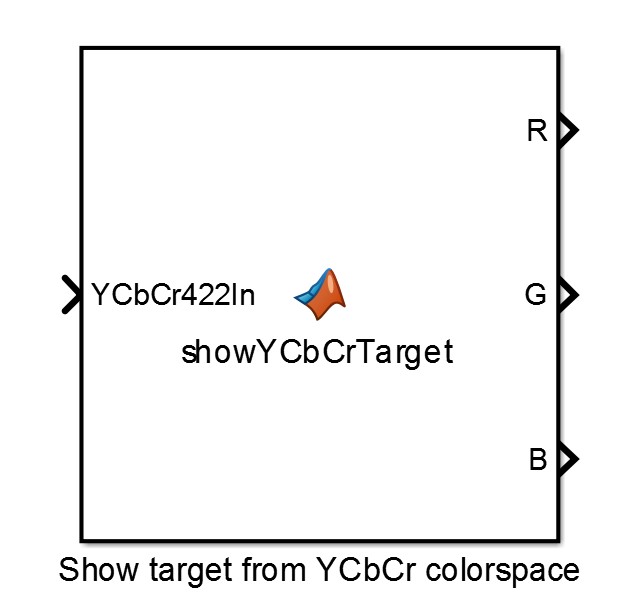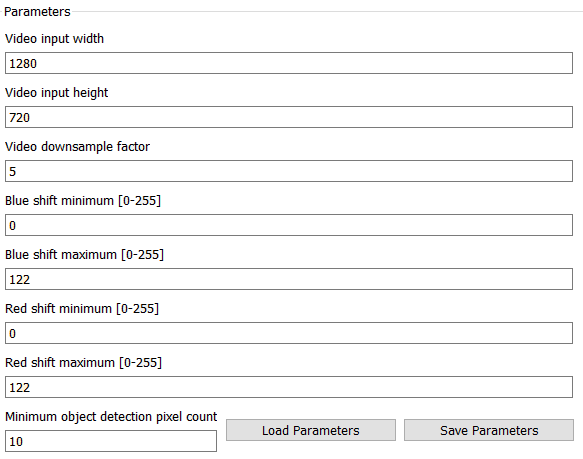

    6.    **Tune** the parameters such that the tracked image of the green ball looks similar to the image below:

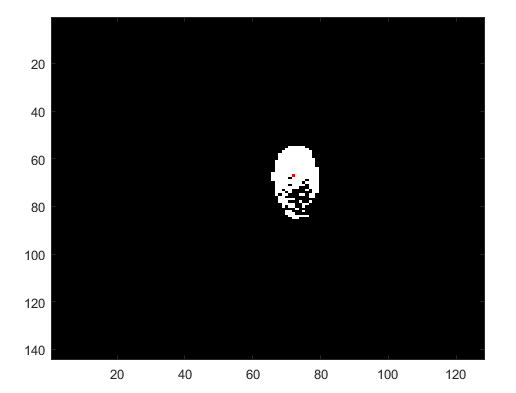

For this the following settings were used:

- Video input width, height, downsample factor = 1280, 720, 5. These should usually not be changed.

- Blue shift min,max = 0, 122

- Red shift min,max = 0, 122

- Minimum object detection pixel count = 10. Increase this if there are many falsely detected target pixels.

Not all of the green ball is tracked in the above image. It is more important to reduce the amount of falsely detected pixels than to detect the entire ball. The red dot indicates the ball centre and is the only thing used in the tracking demo.

    7.    **Save **the tuned parameters by pressing the **save parameters **button in the calibration block.

# Running the demo

After you have completed the color tracking parameter tuning as explained above:

    1.    Open the green ball tracking demo by evaluating:

Green_Ball_Tracking_Mounted

This wil open the following model:

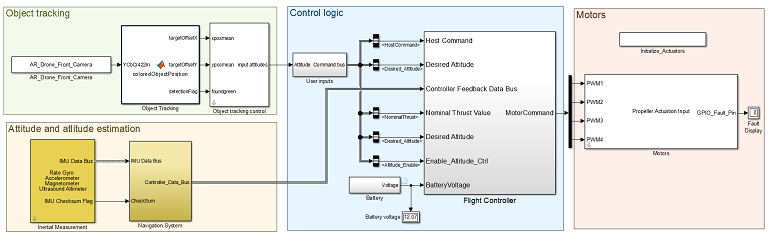

    2.    **Open** the **Object tracking **block within the **Object tracking **area in the Simulink model.

    3.    Click **Load parameters** to load the color tracking parameters you saved in the previous steps and click **OK **to apply these parameters.

    4.    **Build** the model. Either click the **Build** button   or press **control** + **B**.

    5.    **Connect** the Simulink model to the AR Drone. Click the **Connect** **to target **button  

    6.    **Run** the Simulink model. Click the **Run** button  . 

**Note **that if the drone is in a *safe* orientation and the battery voltage is sufficient (10.1 volts or more), the motors will turn on and the drone will begin to hover. A safe orientation means no more than 45 degrees of pitch or roll. 

**Note** that when the motors turn on the battery voltage can drop significantly causing the drone to turn off. The battery needs to be replaced if this is the case.

    7.    If the drone did not start hovering, carefully rotate the drone such that it is horizontal. Once the propellers are on you can let go of the drone and it will hover.

    8.    Hold the green ball so that it is in the field of vision of the drone to make the drone follow the ball.

## Pausing and resuming the demo:

You can **pause** the demo without having to stop or rebuild the model.

    1.    Grab the drone by the joint underneath it. Rotate the drone such that the pitch or roll angle exceeds 45 degrees.

    2.    The drone will try to counter the forced rotation until it determines the angle is unsafe. It will then stop the motors.

    3.    Let go of the drone once the motors have stopped.

To **resume** the demo:

    4.    Grab the drone by the joint underneath it. Rotate the drone such it is horizontal.

    5.    The drone will start the motors and attempt to hover as soon as it determines the pitch and roll angles safe. You can then let go of the drone.

    6.    You can now continue the demo by holding the ball in front of the drone. You can pause and resume the demo as you wish untill the battery runs out.

## Stopping the demo:

It is recommended that you first **pause **the demo before stopping. Stopping the demo without pausing will cause the motors to be killed meaning the drone will fall uncontrolled.

    1.    Grab the drone by the joint underneath it. Rotate the drone such that the pitch or roll angle exceeds 45 degrees.

    2.    The drone will try to counter the forced rotation until it determines the angle is unsafe. It will then stop the motors.

    3.    Let go of the drone once the motors have stopped.

    4.    In Simulink, press the Stop   button.

If you wish to run the demo again you will need to start with the **Build** process, step **4** in the **Running the demo** section.